# Simulation of individual bird in beam to quantify the error in

estimated density

## Power Function

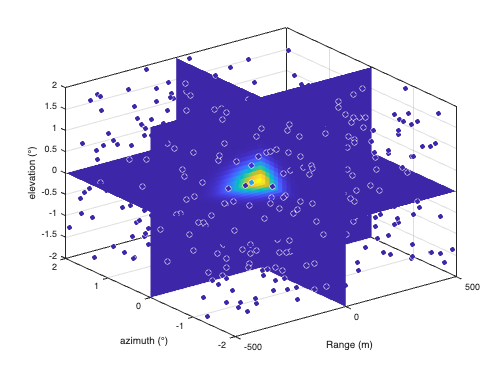

% std dev of the rang, below Eq. 3 in Chilson (2012)
sigma_r = 0.35*250; % m

% compute the std dev of the beam along phi and theta
hpbw = 0.925; % half power beamwiths
sigma_tp = hpbw/2/sqrt(2*log(2)); % below Eq. 2 in Chilson (2012)

% Define the power function in spherical coordinate 
% equivalent to W(r)^2 * f(t,p)^4
% note that r,t,p are actually \delta r etc... (difference to the center of
% the beam)
f_F = @(r,t,p) exp(-r.^2/2/sigma_r^2 -t.^2/sigma_tp^2 - p.^2/sigma_tp^2 );

% Create the same function in cartesian coordinate aligned along the range
% coordinate. 
% We need this function in cartesian coordinate because bird are assumed to
% be distributed homogenously in cartesian coordinate (and note spherical).
% x,y,z are defined from the center of the beam
% r0 is the range from the radar to the center of the beam.
f_F_c = @(x,y,z,r0) f_F(x, atand(y/r0), atand(z/r0) );


% Integral of the power function in spherical coordinate. Not needed
% int_F = integral3(f_F,-inf, inf, -inf, inf, -inf, inf);
% int_F = 106.3202;


% Illustration
[RR,TT,PP] = meshgrid(-500:500,-2:.1:2,-2:.1:2);
figure; hold on;
h = slice(RR,TT,PP,f_F(RR,TT,PP),[0],[0],[0]);
set(h,'edgecolor','none')
xlabel('Range (m)'); ylabel('azimuth (°)'); zlabel('elevation (°)');
% title('f(r,\phi,\theta) = \exp \left( \frac{r}{2\sigma_r^2} \right)')
id = randsample(numel(RR),500);
scatter3(RR(id), TT(id),PP(id),[],f_F(RR(id), TT(id),PP(id)),'filled','MarkerEdgeColor','w')
view(3); grid on; box on;

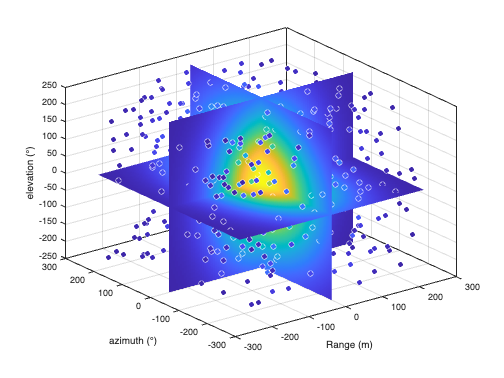


r0 = 30*1000;
[XX,YY,ZZ] = meshgrid(-250:5:250,-250:5:250,-250:5:250);
figure; hold on;
h = slice(XX,YY,ZZ,f_F_c(XX,YY,ZZ,r0),[0],[0],[0]);
set(h,'edgecolor','none')
xlabel('Range (m)'); ylabel('azimuth (°)'); zlabel('elevation (°)');
% title('f(r,\phi,\theta) = \exp \left( \frac{r}{2\sigma_r^2} \right)')
id = randsample(numel(XX),500);
scatter3(XX(id), YY(id),ZZ(id),[],f_F_c(XX(id), YY(id),ZZ(id),r0),'filled','MarkerEdgeColor','w')
view(3); grid on; box on;

## Compute the

% Simulated range (distance from radar in km)
range=[1:10 15:5:50 60:10:100 120:20:160]*1000; 
% Simulated density in bird/km^3 
rho = [1 5 10 15 20 30 40 50 75 100:100:500 700 1000 2000 5000]';  

n_sim=1000;
n_bird=2000;
rho_est=nan(numel(rho),numel(range),n_sim);

for u=1:numel(range)
    for k=1:numel(rho)
        
        % volume needed to get 1000 bird
        V = n_bird/rho(k) * 1000^3; % in m^3

        % x a factor of the sigmas to scale the volume.
        f_dr = @(fac) 2*fac*sigma_r*sqrt(2);
        f_dtp = @(fac) 2*range(u)*tand(fac*sigma_tp);
        f_V = @(fac) f_dr(fac) * f_dtp(fac)^2;

        fac = fminsearch(@(fac) (f_V(fac) - V)^2,1);

%         x = linspace(-fac*sigma_r*sqrt(2),fac*sigma_r*sqrt(2),100);
%         y = linspace(-range(u)*tand(fac*sigma_tp),range(u)*tand(fac*sigma_tp),100);
%         z=y;
% 
%         [XX,YY,ZZ] = ndgrid(x,y,z);

        % Check volume
        % median(diff(x))*median(diff(z))*median(diff(y)) * numel(XX)
        % (x(end)-x(1)) * (y(end)-y(1)) * (z(end)-z(1))

        % F = f_F_c(XX,YY,ZZ,range(u));

%         figure; hold on;
%         h = slice(XX,YY,ZZ,F,[0],[0],[0]);
%         set(h,'edgecolor','none')
%         xlabel('Range (m)'); ylabel('azimuth (°)'); zlabel('elevation (°)');

        n_bird_eff=round(rho(k)/1000^3*f_V(fac));
        XYZ = rand(n_bird_eff,n_sim,3);
        tmp = reshape([f_dr(fac) f_dtp(fac) f_dtp(fac)],1,1,3);
        XYZ = XYZ .* tmp - tmp/2;

        F_sim = f_F_c(XYZ(:,:,1), XYZ(:,:,2), XYZ(:,:,3),range(u));
        
        int_F_c = integral3(@(x,y,z) f_F_c(x,y,z,range(u)),...
            -f_dr(fac)/2, f_dr(fac)/2, -f_dtp(fac)/2, f_dtp(fac)/2, -f_dtp(fac)/2, f_dtp(fac)/2);

        % From Chilson (2012) Eq. 7. -> sum_i^n F_i = 1/V * n * V_rad
        nb_bird_est = sum(F_sim) * f_V(fac) / int_F_c;
        dens_est(k,u,:) = nb_bird_est/n_bird_eff*rho(k);

    end
end

## Fit Gamma

phat=nan(numel(rho),numel(range),2);
lamt=nan(numel(rho),numel(range));
for u=1:numel(range)
    for k=1:numel(rho)
        phat(k,u,:)=gamfit(dens_est(k,u,:));
        lamt(k,u)=poissfit(dens_est(k,u,:));
    end
end
phat(1,1,2)=nan;
lamt(1,1)=nan;

## Figure

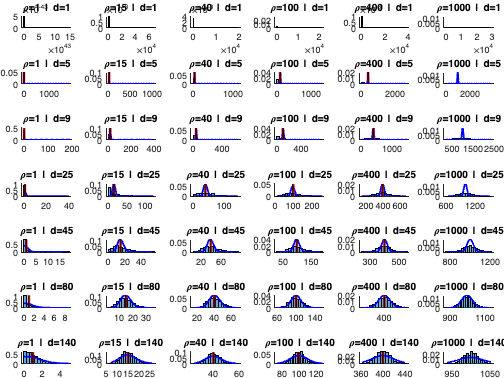

figure; tiledlayout(7,6,'TileSpacing','tight','Padding','tight')
for u=1:4:numel(range)
    for k=1:3:numel(rho)
        nexttile; hold on;
        histogram(dens_est(k,u,:),'Normalization','pdf')
        tmp =round(linspace(min(dens_est(k,u,:)),max(dens_est(k,u,:)),200));
        %plot(tmp, gampdf(tmp,phat(k,u,1),phat(k,u,2)),'-b','linewidth',2)
         plot(tmp, poisspdf(tmp,lamt(k,u)),'-b','linewidth',2)
        xline(rho(k),'r','linewidth',3)
        xline(mean(dens_est(k,u,:)),'k','linewidth',2)
        title("\rho="+rho(k)+" | d="+range(u)/1000)
    end
end

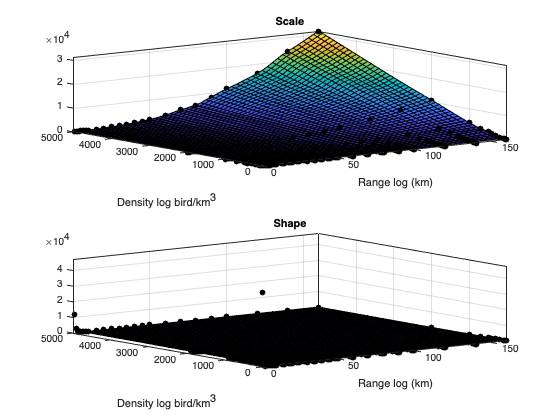


%
[tmp1, tmp2]=meshgrid(range/1000,rho);
tmp3=phat(:,:,1);
id=~isnan(tmp3);
fitphat1 = fit(([tmp1(id) tmp2(id)]),tmp3(id),'cubicinterp');
tmp4=phat(:,:,2);
id=~isnan(tmp4);
fitphat2 = fit(([tmp1(id) tmp2(id)]),tmp4(id),'cubicinterp');
tmp5=lamt(:,:);
id=~isnan(tmp5);
fitlamt = fit(([tmp1(id) tmp2(id)]),tmp5(id),'cubicinterp');


figure;
nexttile; hold on; title('Scale')
scatter3(tmp1(id), tmp2(id), tmp3(id),'k','filled')
plot(fitphat1)
ylabel('Density log bird/km^3')
xlabel('Range log (km)')
view(3)
nexttile; hold on; title('Shape')
scatter3(tmp1(id), tmp2(id), tmp4(id),'k','filled')
plot(fitphat2)
ylabel('Density log bird/km^3')
xlabel('Range log (km)')
view(3)

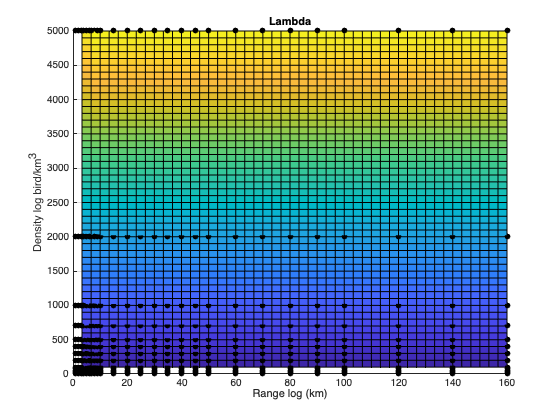


figure; hold on; title('Lambda')
scatter3(tmp1(id), tmp2(id), tmp5(id),'k','filled')
plot(fitlamt)
ylabel('Density log bird/km^3')
xlabel('Range log (km)')

## P(d_true|d_est)

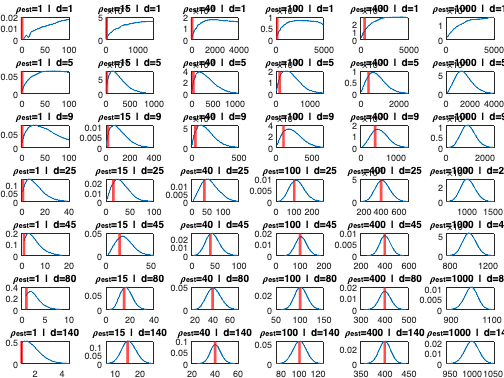

r0=15;
d_est=100;


figure; tiledlayout(7,6,'TileSpacing','tight','Padding','tight')
for u=1:4:numel(range)
    for k=1:3:numel(rho)
        nexttile; hold on; box on;
        r0=range(u)/1000;
        d_est=rho(k);
        d_true = logspace(log10(d_est)-1,log10(d_est)+2,500);
        p = gampdf(d_est, fitphat1(repmat(r0,size(d_true)),d_true), fitphat2(repmat(r0,size(d_true)),d_true));
        id=find(p./nansum(p)>.0001);
        d_true = linspace(d_true(id(1)),d_true(id(end)),500);
        p = gampdf(d_est, fitphat1(repmat(r0,size(d_true)),d_true), fitphat2(repmat(r0,size(d_true)),d_true));
        xline(d_est,'r','linewidth',3)
        plot(d_true,p)
        title("\rho_{est}="+rho(k)+" | d="+range(u)/1000)
        %xlim([0 5000])
    end
end

## Check true data

scans_filepath = load_rd("KBYX", datetime("19-Apr-2019 01:00"));
rd = read_rd(scans_filepath, 'maxAlt', 2000);
r_lim = 50000;
gridsize = num2str(r_lim/1000)+"km";
[df, rd] = load_F_elev("data/" + gridsize + "/", rd);
g = create_grid(df, rd);
[gX,gY,~]=meshgrid(g.x,g.y,g.z);
[gLON,gLAT,gZ]=meshgrid(g.lon,g.lat,g.z);
[F, data, info] = construct_F(rd, df, g);
szf = size(F);

Not working yet! 

figure; tiledlayout('flow','TileSpacing','tight','Padding','tight');
for i_elev=1:min(5,numel(rd.dz.sweeps))
    nexttile;
    data = squeeze(D(i_elev,:,:));
    r = squeeze(R(i_elev,:,:));
    az = squeeze(A(i_elev,:,:));
    imagesc(az(1,~isnan(az(1,:))),r(~isnan(r(:,1)),1),data(~isnan(r(:,1)),~isnan(az(1,:))),'AlphaData',~isnan(data(~isnan(r(:,1)),~isnan(az(1,:)))))
    ylim([0 150000]); colorbar; 
    clim([0 zmax]);
end


i_elev=1;
data = squeeze(D(i_elev,:,:));
r = squeeze(R(i_elev,:,:));
az = squeeze(A(i_elev,:,:));
figure; tiledlayout(6,6,'TileSpacing','tight','Padding','tight')
for u=4:4:numel(range)
    for i=1:6
        [~,id]=min(abs(range(u)-r(:,1)));
        smpl = data(randi([6 size(data,1)-5])+(-5:5),id+(-5:5));
        while sum(~isnan(smpl(:)))<40
            smpl = data(randi([6 size(data,1)-5])+(-5:5),id+(-5:5));
        end
        [~,k] =min(abs(rho-mean(smpl(:),'omitnan')));
        nexttile; hold on;
        % histogram(smpl,'Normalization','pdf')
        histfit(smpl(:),[],'gamma')
        % tmp = linspace(min(dens_est(k,u,:)),max(dens_est(k,u,:)),200);
        tmp = linspace(min(smpl(:)),max(smpl(:)),200);
        plot(tmp, 1000*gampdf(tmp,phat(k,u,1),phat(k,u,2)),'-b','linewidth',2)
        xline(rho(k),'r','linewidth',3)
        % xline(mean(dens_est(k,u,:)),'k','linewidth',2)
        title("\rho="+rho(k)+" | d="+range(u)/1000)
    end
end